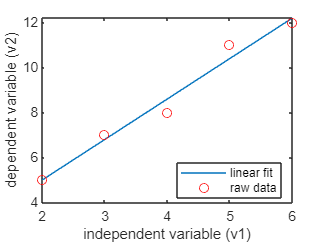

v1 = [2,3,4,5,6];
b = [5,7,8,11,12];

A = cat(2, ones(1, 5)', v1');

[c1, c2] = LSsolver(A, b);

plot(v1, c1 + c2*v1);
hold on;
plot(v1, b, "-o", LineStyle="none", Color="red");

legend("linear fit", "raw data", location="best");
xlabel("independent variable (v1)");
ylabel("dependent variable (v2)");


disp(c1 + c2*4.6);

    9.6800



function [c1, c2] = LSsolver(A, b)
    xls = inv(A'*A) * (A'*b');
    c1 = xls(1);
    c2 = xls(2);
end

when v1 is 4.6, v2 is predicted to be 9.68